# DEMO_febio_0019_vessel_pressure_inflate

Below is a demonstration for:

- Building geometry for a cylindrical vessel with tetrahedral elements

- Defining the boundary conditions 

- Coding the febio structure

- Running the model    

- Importing and visualizing the displacement results

## Keywords

- febio_spec version 2.5

- febio, FEBio

- vessel, cylinder

- prescribed pressure

- tetrahedral elements, tet4

- tube, cylindrical

- static, solid

- hyperelastic, Ogden

- displacement logfile

- stress logfile

clear; close all; clc;

## Plot settings

fontSize=20;
faceAlpha1=0.8;
markerSize=40;
lineWidth=3;

## Control parameters

% Path names
defaultFolder = fileparts(fileparts(mfilename('fullpath')));
savePath=fullfile(defaultFolder,'data','temp');

% Defining file names
febioFebFileNamePart='tempModel';
febioFebFileName=fullfile(savePath,[febioFebFileNamePart,'.feb']); %FEB file name
febioLogFileName=fullfile(savePath,[febioFebFileNamePart,'.txt']); %FEBio log file name
febioLogFileName_disp=[febioFebFileNamePart,'_disp_out.txt']; %Log file name for exporting displacement
febioLogFileName_force=[febioFebFileNamePart,'_force_out.txt']; %Log file name for exporting force

%Specifying geometry parameters
pointSpacing=1; 
radiusOuter1=10;
radiusInner1=9;
radiusOuter2=9;
radiusInner2=7;
vesselLength=60;

%Load
pressureValue=5e-3; 

%Material parameter set
c1=0.03; %Shear-modulus-like parameter
m1=2; %Material parameter setting degree of non-linearity
k_factor=1e2; %Bulk modulus factor 
k=c1*k_factor; %Bulk modulus

% FEA control settings
numTimeSteps=20; %Number of time steps desired
max_refs=25; %Max reforms
max_ups=0; %Set to zero to use full-Newton iterations
opt_iter=12; %Optimum number of iterations
max_retries=10; %Maximum number of retires
dtmin=(1/numTimeSteps)/100; %Minimum time step size
dtmax=1/numTimeSteps; %Maximum time step size

## Creating model boundary polygons

nRad=round((2*pi*mean([radiusOuter1 radiusOuter2]))/pointSpacing); %Number of radial steps

t=linspace(0,2*pi,nRad)'; %Angles
t=t(1:end-1); %take away last which equals start
v1_Outer=[-(vesselLength/2)*ones(size(t)) radiusOuter1*sin(t) radiusOuter1*cos(t)]; %Circular coordinates

t=linspace(0,2*pi,nRad)'; %Angles
t=t(1:end-1); %take away last which equals start
v2_Outer=[(vesselLength/2)*ones(size(t)) radiusOuter2*sin(t) radiusOuter2*cos(t)]; %Circular coordinates

nRad=round((2*pi*mean([radiusInner1 radiusInner2]))/pointSpacing); %Number of radial steps

t=linspace(0,2*pi,nRad)'; %Angles
t=t(1:end-1); %take away last which equals start
v1_Inner=[-(vesselLength/2)*ones(size(t)) radiusInner1*sin(t) radiusInner1*cos(t)]; %Circular coordinates

t=linspace(0,2*pi,nRad)'; %Angles
t=t(1:end-1); %take away last which equals start
v2_Inner=[(vesselLength/2)*ones(size(t)) radiusInner2*sin(t) radiusInner2*cos(t)]; %Circular coordinates

Plotting model boundary polygons

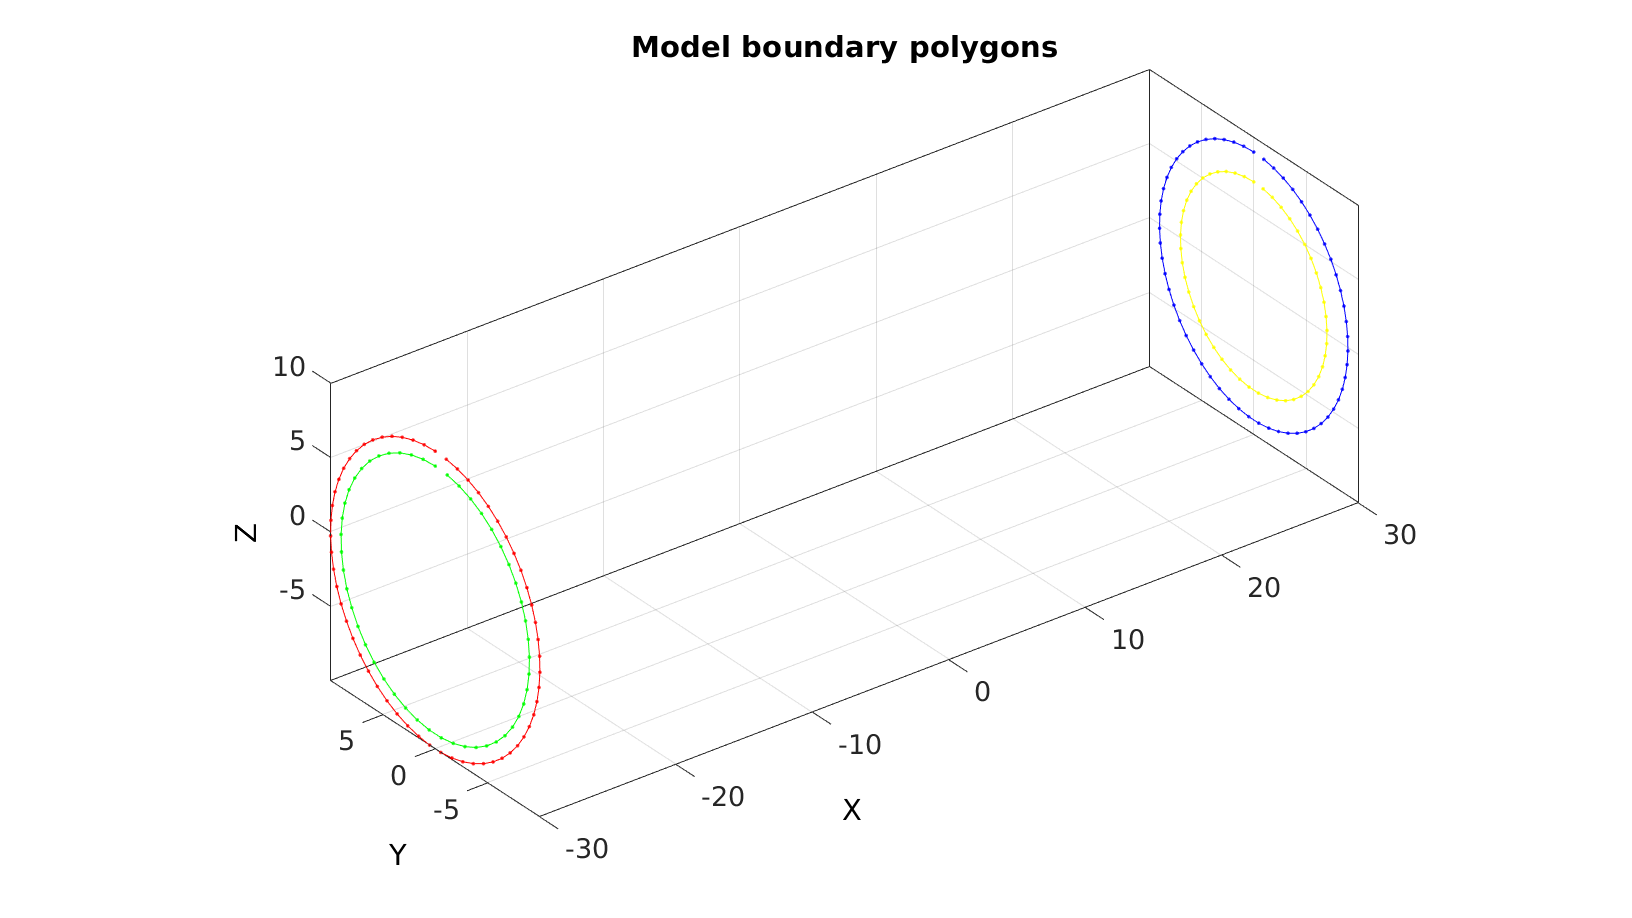

cFigure; 
hold on; 
title('Model boundary polygons','FontSize',fontSize);
plotV(v1_Outer,'r.-')
plotV(v1_Inner,'g.-')
plotV(v2_Outer,'b.-')
plotV(v2_Inner,'y.-')
axisGeom(gca,fontSize);


drawnow;

## Creating model boundary surfaces

% controlStructLoft.numSteps=17; 
controlStructLoft.closeLoopOpt=1; 
controlStructLoft.patchType='tri';

%Meshing outer surface
[F1,V1]=polyLoftLinear(v1_Outer,v2_Outer,controlStructLoft); 
F1=fliplr(F1); %Invert orientation

%Meshing inner surface
[F2,V2]=polyLoftLinear(v1_Inner,v2_Inner,controlStructLoft); 

%Meshing left
[F3,V3]=regionTriMesh3D({v1_Outer,v1_Inner},pointSpacing,0,'linear');
F3=fliplr(F3); %Invert orientation

%Meshing right
[F4,V4]=regionTriMesh3D({v2_Outer,v2_Inner},pointSpacing,0,'linear');

%Merging surface sets
[Fv,Vv,Cv]=joinElementSets({F1,F2,F3,F4},{V1,V2,V3,V4});
[Fv,Vv]=mergeVertices(Fv,Vv);
Fv=fliplr(Fv);

Plotting model boundary surfaces

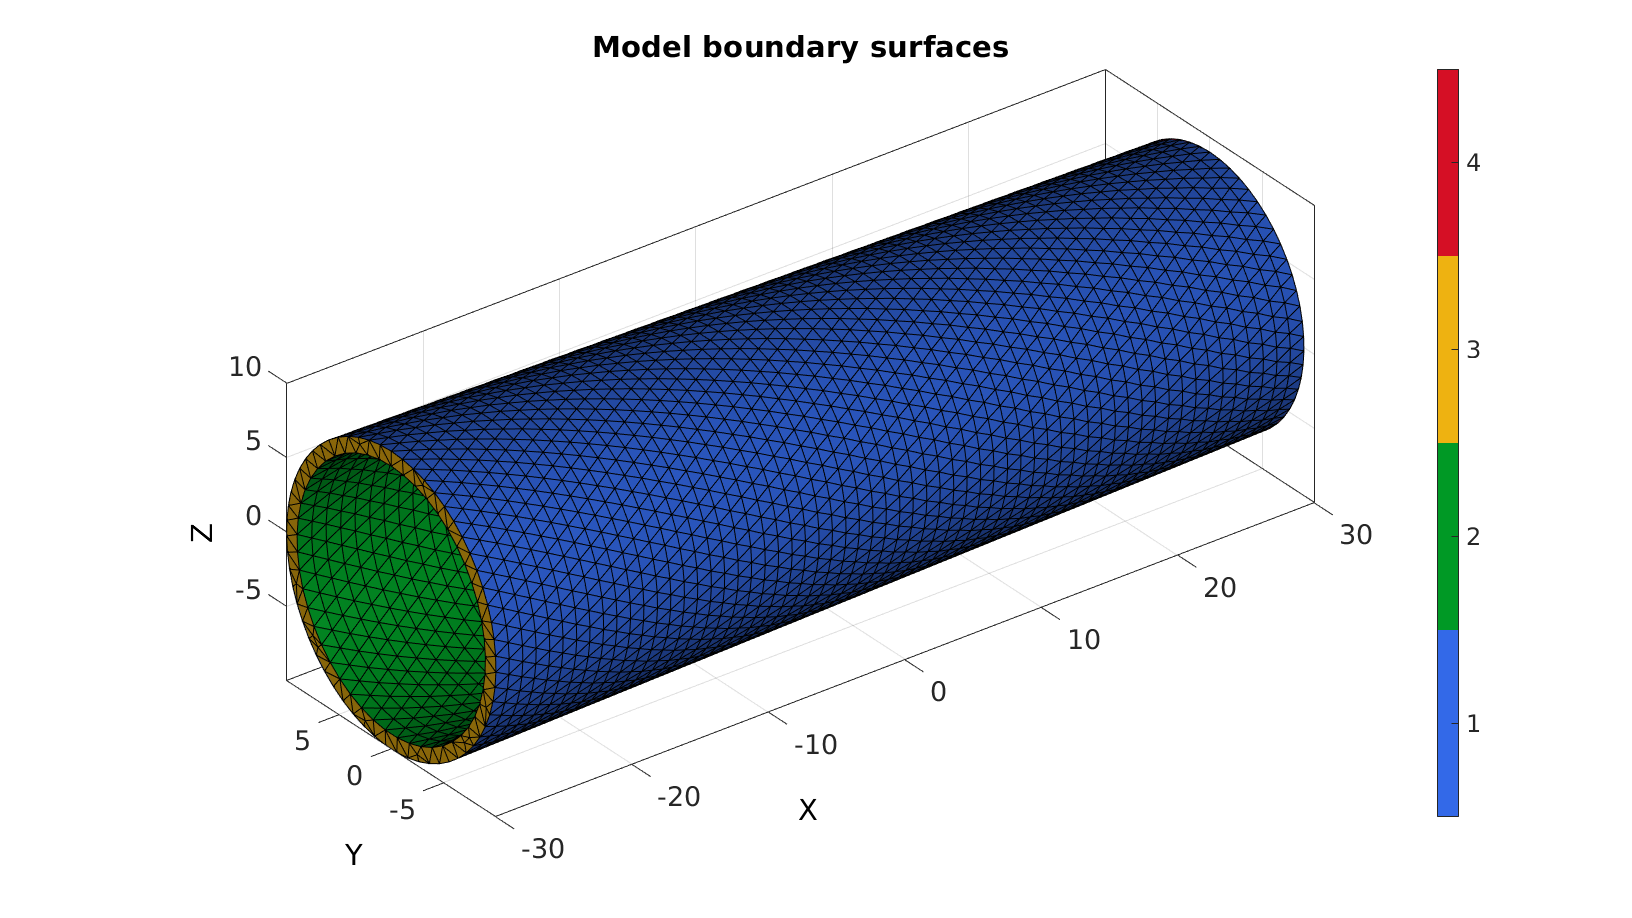

cFigure; 
hold on; 
title('Model boundary surfaces','FontSize',fontSize);

gpatch(Fv,Vv,Cv);
% patchNormPlot(Fv,Vv);

icolorbar; 
colormap(gjet(4)); 

axisGeom(gca,fontSize);
camlight headlight;

drawnow;

## Tetrahedral meshing of vessel

faceBoundaryMarker=Cv;
[V_regions]=getInnerPoint(Fv,Vv);
[regionA]=tetVolMeanEst(Fv,Vv); %Volume for regular tets
stringOpt='-pq1.2AaY';

inputStruct.stringOpt=stringOpt;
inputStruct.Faces=Fv;
inputStruct.Nodes=Vv;
inputStruct.holePoints=[];
inputStruct.faceBoundaryMarker=faceBoundaryMarker; %Face boundary markers
inputStruct.regionPoints=V_regions; %region points
inputStruct.regionA=regionA;
inputStruct.minRegionMarker=2; %Minimum region marker

% Mesh model using tetrahedral elements using tetGen
[meshOutput]=runTetGen(inputStruct); %Run tetGen

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 09-Aug-2019 08:38:21
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 09-Aug-2019 08:38:21
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 09-Aug-2019 08:38:21
--- Running TetGen to mesh input boundary--- 09-Aug-2019 08:38:21
Opening /mnt/data/MATLAB/GIBBON/data/temp/temp.smesh.
Delaunizing vertices...
Delaunay seconds:  0.49869
Creating surface mesh ...
Surface mesh seconds:  0.015215
Recovering boundaries...
Boundary recovery seconds:  0.039717
Removing exterior tetrahedra ...
Spreading region attributes.
Exterior tets removal seconds:  0.017173
Recovering Delaunayness...
Delaunay recovery seconds:  0.011799
Refining mesh...
Refinement seconds:  0.116346
Optimizing mesh...
Optimization seconds:  0.008001

Writing /mnt/data/MATLAB/GIBBON/data/temp/temp.1.node.
Writing /mnt/data/MATLAB/GIBBON/data/t

Access model element and patch data

Fb=meshOutput.facesBoundary;
Cb=meshOutput.boundaryMarker;
V=meshOutput.nodes;
CE=meshOutput.elementMaterialID;
E=meshOutput.elements;

Visualizing mesh using `meshView`, see also `anim8`

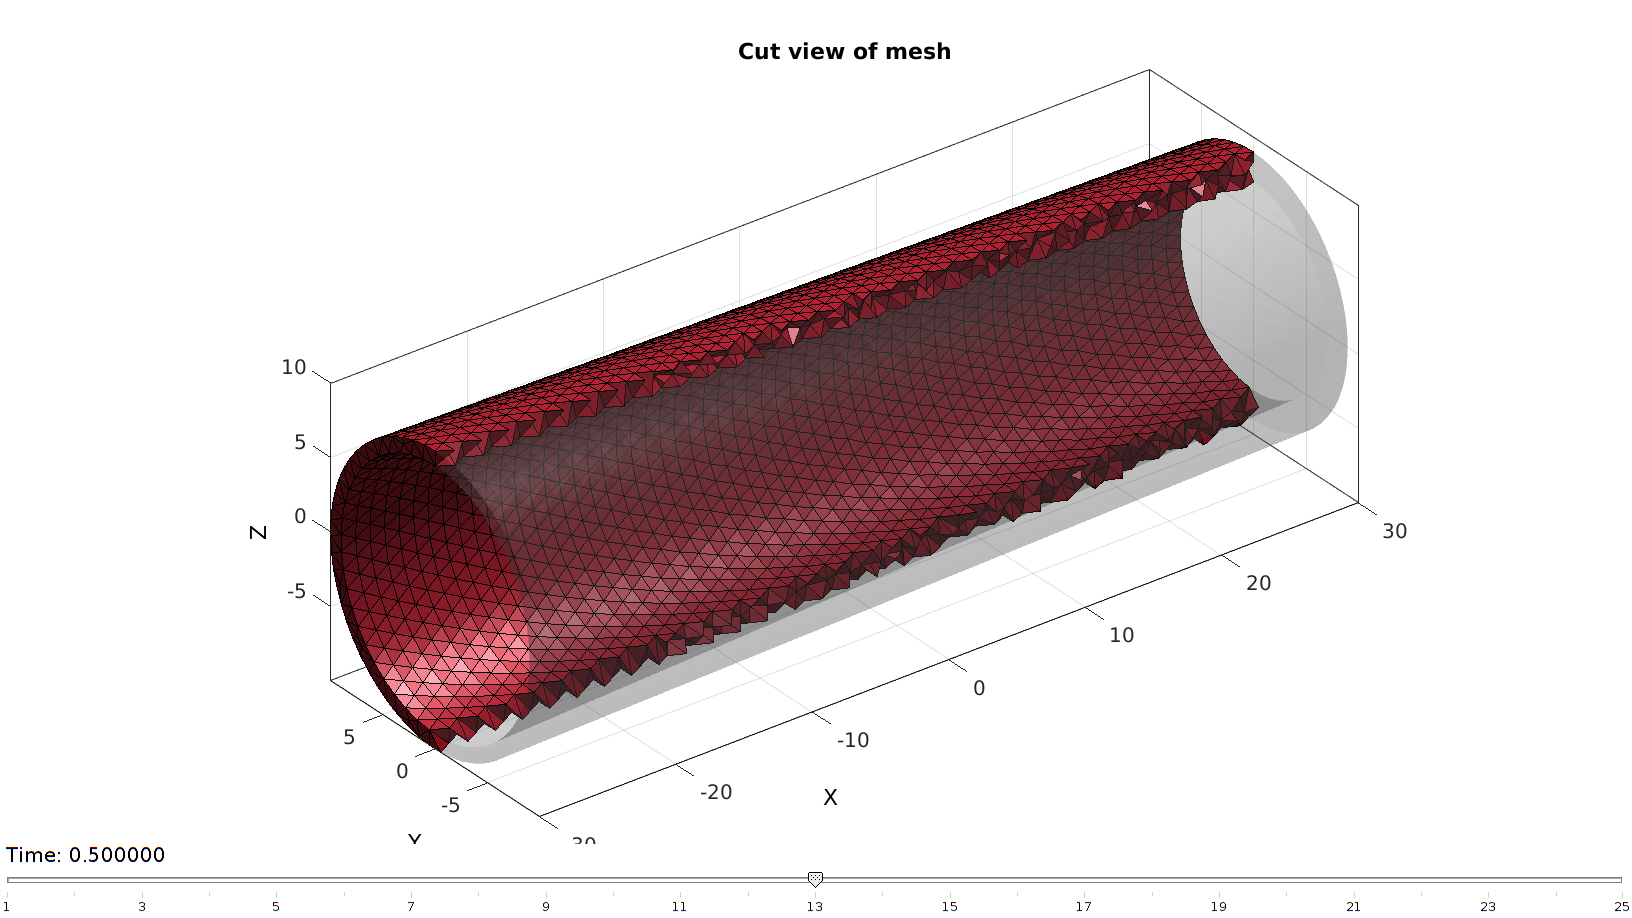

meshView(meshOutput,[]);

## Defining the boundary conditions

The visualization of the model boundary shows colors for each side of the cube. These labels can be used to define boundary conditions. 

%Define supported node set
bcSupportList=unique(Fb(ismember(Cb,[3 4]),:)); %Node set part of selected face

F_pressure=fliplr(Fb(Cb==2,:));

Visualizing boundary conditions. Markers plotted on the semi-transparent model denote the nodes in the various boundary condition lists. 

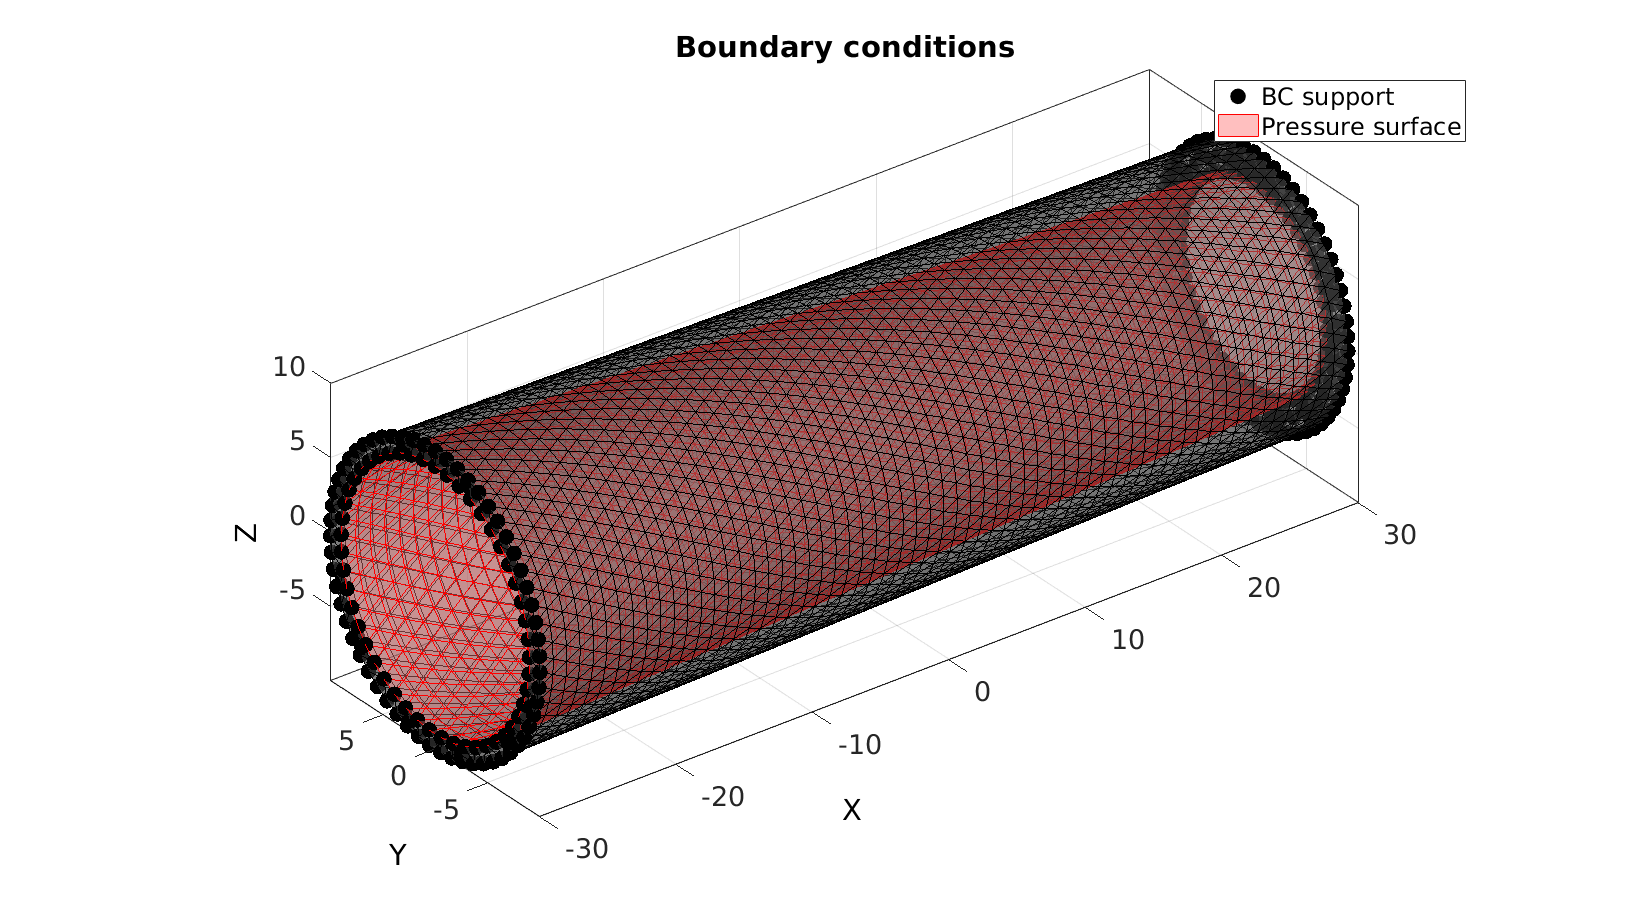

hf=cFigure;
title('Boundary conditions','FontSize',fontSize);
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'kw','k',0.5);

hl(1)=plotV(V(bcSupportList,:),'k.','MarkerSize',markerSize);
hl(2)=gpatch(F_pressure,V,'rw','r',0.5);

legend(hl,{'BC support','Pressure surface'});

axisGeom(gca,fontSize);
camlight headlight; 

drawnow;

## Defining the FEBio input structure

See also `febioStructTemplate` and `febioStruct2xml` and the FEBio user manual.

%Get a template with default settings 
[febio_spec]=febioStructTemplate;

%febio_spec version 
febio_spec.ATTR.version='2.5'; 

%Module section
febio_spec.Module.ATTR.type='solid'; 

%Control section
febio_spec.Control.analysis.ATTR.type='static';
febio_spec.Control.time_steps=numTimeSteps;
febio_spec.Control.step_size=1/numTimeSteps;
febio_spec.Control.time_stepper.dtmin=dtmin;
febio_spec.Control.time_stepper.dtmax=dtmax; 
febio_spec.Control.time_stepper.max_retries=max_retries;
febio_spec.Control.time_stepper.opt_iter=opt_iter;
febio_spec.Control.max_refs=max_refs;
febio_spec.Control.max_ups=max_ups;

%Material section
febio_spec.Material.material{1}.ATTR.type='Ogden';
febio_spec.Material.material{1}.ATTR.id=1;
febio_spec.Material.material{1}.c1=c1;
febio_spec.Material.material{1}.m1=m1;
febio_spec.Material.material{1}.c2=c1;
febio_spec.Material.material{1}.m2=-m1;
febio_spec.Material.material{1}.k=k;

%Geometry section
% -> Nodes
febio_spec.Geometry.Nodes{1}.ATTR.name='nodeSet_all'; %The node set name
febio_spec.Geometry.Nodes{1}.node.ATTR.id=(1:size(V,1))'; %The node id's
febio_spec.Geometry.Nodes{1}.node.VAL=V; %The nodel coordinates

% -> Elements
febio_spec.Geometry.Elements{1}.ATTR.type='tet4'; %Element type of this set
febio_spec.Geometry.Elements{1}.ATTR.mat=1; %material index for this set 
febio_spec.Geometry.Elements{1}.ATTR.name='Vessel'; %Name of the element set
febio_spec.Geometry.Elements{1}.elem.ATTR.id=(1:1:size(E,1))'; %Element id's
febio_spec.Geometry.Elements{1}.elem.VAL=E;

% -> NodeSets
febio_spec.Geometry.NodeSet{1}.ATTR.name='bcSupportList';
febio_spec.Geometry.NodeSet{1}.node.ATTR.id=bcSupportList(:);

% -> Surfaces
febio_spec.Geometry.Surface{1}.ATTR.name='Pressure_surface';
febio_spec.Geometry.Surface{1}.tri3.ATTR.lid=(1:size(F_pressure,1))';
febio_spec.Geometry.Surface{1}.tri3.VAL=F_pressure;

%Boundary condition section 
% -> Fix boundary conditions
febio_spec.Boundary.fix{1}.ATTR.bc='x';
febio_spec.Boundary.fix{1}.ATTR.node_set=febio_spec.Geometry.NodeSet{1}.ATTR.name;
febio_spec.Boundary.fix{2}.ATTR.bc='y';
febio_spec.Boundary.fix{2}.ATTR.node_set=febio_spec.Geometry.NodeSet{1}.ATTR.name;
febio_spec.Boundary.fix{3}.ATTR.bc='z';
febio_spec.Boundary.fix{3}.ATTR.node_set=febio_spec.Geometry.NodeSet{1}.ATTR.name;

%Loads
febio_spec.Loads.surface_load{1}.ATTR.type='pressure';
febio_spec.Loads.surface_load{1}.ATTR.surface=febio_spec.Geometry.Surface{1}.ATTR.name;
febio_spec.Loads.surface_load{1}.pressure.VAL=pressureValue;
febio_spec.Loads.surface_load{1}.pressure.ATTR.lc=1;

%Output section 
% -> log file
febio_spec.Output.logfile.ATTR.file=febioLogFileName;
febio_spec.Output.logfile.node_data{1}.ATTR.file=febioLogFileName_disp;
febio_spec.Output.logfile.node_data{1}.ATTR.data='ux;uy;uz';
febio_spec.Output.logfile.node_data{1}.ATTR.delim=',';
febio_spec.Output.logfile.node_data{1}.VAL=1:size(V,1);

febio_spec.Output.logfile.node_data{2}.ATTR.file=febioLogFileName_force;
febio_spec.Output.logfile.node_data{2}.ATTR.data='Rx;Ry;Rz';
febio_spec.Output.logfile.node_data{2}.ATTR.delim=',';
febio_spec.Output.logfile.node_data{2}.VAL=1:size(V,1);

## Quick viewing of the FEBio input file structure

The `febView` function can be used to view the xml structure in a MATLAB figure window. 

`febView(febio_spec); %Viewing the febio file` febView(febio_spec)

## Exporting the FEBio input file

Exporting the febio_spec structure to an FEBio input file is done using the `febioStruct2xml` function. 

febioStruct2xml(febio_spec,febioFebFileName); %Exporting to file and domNode

Error using fprintf
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in cell2txtfile (line 63)
        fprintf(fid,'%s\r\n', T{:});

Error in febioStruct2xml>textModeElementAttributeParse (line 321)
cell2txtfile(fileName,totalTextCell,0,0); %Export to text file

Error in 

## Running the FEBio analysis

To run the analysis defined by the created FEBio input file the `runMonitorFEBio` function is used. The input for this function is a structure defining job settings e.g. the FEBio input file name. The optional output runFlag informs the user if the analysis was run succesfully. 

febioAnalysis.run_filename=febioFebFileName; %The input file name
febioAnalysis.run_logname=febioLogFileName; %The name for the log file
febioAnalysis.disp_on=1; %Display information on the command window
febioAnalysis.disp_log_on=1; %Display convergence information in the command window
febioAnalysis.runMode='external';%'internal';
febioAnalysis.t_check=0.25; %Time for checking log file (dont set too small)
febioAnalysis.maxtpi=1e99; %Max analysis time
febioAnalysis.maxLogCheckTime=3; %Max log file checking time

[runFlag]=runMonitorFEBio(febioAnalysis);%START FEBio NOW!!!!!!!!

## Import FEBio results

if runFlag==1 %i.e. a succesful run
    
    % Importing nodal displacements from a log file
    [time_mat, N_disp_mat,~]=importFEBio_logfile(fullfile(savePath,febioLogFileName_disp)); %Nodal displacements    
    time_mat=[0; time_mat(:)]; %Time

    N_disp_mat=N_disp_mat(:,2:end,:);
    sizImport=size(N_disp_mat);
    sizImport(3)=sizImport(3)+1;
    N_disp_mat_n=zeros(sizImport);
    N_disp_mat_n(:,:,2:end)=N_disp_mat;
    N_disp_mat=N_disp_mat_n;
    DN=N_disp_mat(:,:,end);
    DN_magnitude=sqrt(sum(DN(:,3).^2,2));
    V_def=V+DN;
    [CF]=vertexToFaceMeasure(Fb,DN_magnitude);

Plotting the simulated results using `anim8` to visualize and animate deformations 

    % Create basic view and store graphics handle to initiate animation
    hf=cFigure; %Open figure  
    gtitle([febioFebFileNamePart,': Press play to animate']);
    hp=gpatch(Fb,V_def,CF,'k',1); %Add graphics object to animate
    gpatch(Fb,V,0.5*ones(1,3),'none',0.25); %A static graphics object
    
    axisGeom(gca,fontSize); 
    colormap(gjet(250)); colorbar;
    caxis([0 max(DN_magnitude)]);    
    axis([min(V_def(:,1)) max(V_def(:,1)) min(V_def(:,2)) max(V_def(:,2)) min(V_def(:,3)) max(V_def(:,3))]); %Set axis limits statically
    camlight headlight;        
        
    % Set up animation features
    animStruct.Time=time_mat; %The time vector    
    for qt=1:1:size(N_disp_mat,3) %Loop over time increments        
        DN=N_disp_mat(:,:,qt); %Current displacement
        DN_magnitude=sqrt(sum(DN.^2,2)); %Current displacement magnitude
        V_def=V+DN; %Current nodal coordinates
        [CF]=vertexToFaceMeasure(Fb,DN_magnitude); %Current color data to use
        
        %Set entries in animation structure
        animStruct.Handles{qt}=[hp hp]; %Handles of objects to animate
        animStruct.Props{qt}={'Vertices','CData'}; %Properties of objects to animate
        animStruct.Set{qt}={V_def,CF}; %Property values for to set in order to animate
    end        
    anim8(hf,animStruct); %Initiate animation feature    
    drawnow;

end

<<gibbVerySmall.gif>>

***GIBBON***  [www.gibboncode.org](www.gibboncode.org)

*Kevin Mattheus Moerman*, [gibbon.toolbox@gmail.com](gibbon.toolbox@gmail.com)

***GIBBON footer text*** 

License: [https://github.com/gibbonCode/GIBBON/blob/master/LICENSE](https://github.com/gibbonCode/GIBBON/blob/master/LICENSE)

GIBBON: The Geometry and Image-based Bioengineering add-On. A toolbox for image segmentation, image-based modeling, meshing, and finite element analysis.

Copyright (C) 2019 Kevin Mattheus Moerman

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).